# **LAB7 - CURVE ROC E KAPLAM-MEIER**

#### **CURVE ROC**

*Load the ex1.mat file containing data concerning 50 subjects (20 affected (disease=1), 30 not affected (disease=0)) for which the concentration of a certain marker molecule was measured.*

*• Compute sensitivity, specificity, accuracy for this threshold: concentration > 1.3*

*• Draw the ROC curve*

La classificazione di un soggetto avviene attraverso il confronto con una threshold. Gli affetti dalla patologia sono classificati come **positivi **se il valore di riferimento è superiore alla soglia, altrimenti sono classificati come **negativi.**

Una **matrice di confusione **relaziona la classificazione predetta dal modello e quella effettiva, categorizzando un campione come:

- **TP [True Positive]**:  Positivo classificato CORRETTAMENTE come Positivo dal modello

- **TN [True Negative]**:  Negativo classificato CORRETTAMENTE come Negativo dal modello

- **FP [False Positive]**:  Negativo classificato ERRONEAMENTE come Positivo dal modello

- **FN [False Negative]**:  Positivo classificato ERRONEAMENTE come Negativo dal modello

Da queste classificazioni la performance del modello è valutato sulla base di:

$Sensitività = \frac{TP}{TP+FN} $        ovvero la capacità del modello di riconoscere correttamente un caso patologico (*TRUE POSITIVE RATE*)

$Specificità = \frac{TN}{TN+FP}
$        ovvero la capacità del modello di non diagnosticare casi patologici

$Accuratezza = \frac{TP+TN}{TP+TN+FP+FN}$        ovvero la capacità del modello di classificare correttamente i soggetti

I parametri dei 50 soggetti sono contenuti in `concentration, `mentre il *ground-truth *è contenuto in `disease`

load("ex1.mat");
disease = logical(disease);

Scegliamo la soglia e classifichiamo i soggetti sulla base di essa.

thr = 1.3;
result = concentration > thr;

Si calcolano ora i parametri del modello

TP = nnz(disease == 1 & result == 1);
TN = nnz(disease == 0 & result == 0);
FP = nnz(disease == 1 & result == 0);
FN = nnz(disease == 0 & result == 1);
sensitivity = TP/(TP+FN)

sensitivity = 1

specificity = TN/(TN+FP)

specificity = 0.8108

accuracy = (TP+TN)/numel(disease)

accuracy = 0.8600

Una **curva ROC (Receiver Operating Characteristic) **è un grafico che mette in relazione il *False Positive Rate *($1-Specificità
$)  e la $Sensitività
$ del modello al variare del valore soglia utilizzato per la classificazione. La bisettrice I-III di questo grafico è la curva ROC attesa da un modello che classifica casualmente i soggetti: il modello prodotto viene definito buono se i suoi valori sono situati sopra la bisettrice. La bontà di un modello è quindi valutata sulla base del metodo **AUC (Area Under the Curve), **che tanto più è vicina a 1 quanto migliore è il modello. 

Si definiscono tutte le soglie per le classificazioni: le soglie vengono scelte in modo da classificare come positivi i valori via via sempre maggiori. Si calcolano poi i valori di specificità e sensitività

specificity = [];
sensitivity = [];
thr = sort(concentration);
for i = 1:numel(thr) 
    result = concentration > thr(i);
    TP = nnz(disease == 1 & result == 1);
    TN = nnz(disease == 0 & result == 0);
    FP = nnz(disease == 1 & result == 0);
    FN = nnz(disease == 0 & result == 1);
    sensitivity = cat(1, sensitivity, TP/(TP+FN));
    specificity = cat(1, specificity, TN/(TN+FP));
end

Plottaggio della curva ROC, con la bisettrice I-III

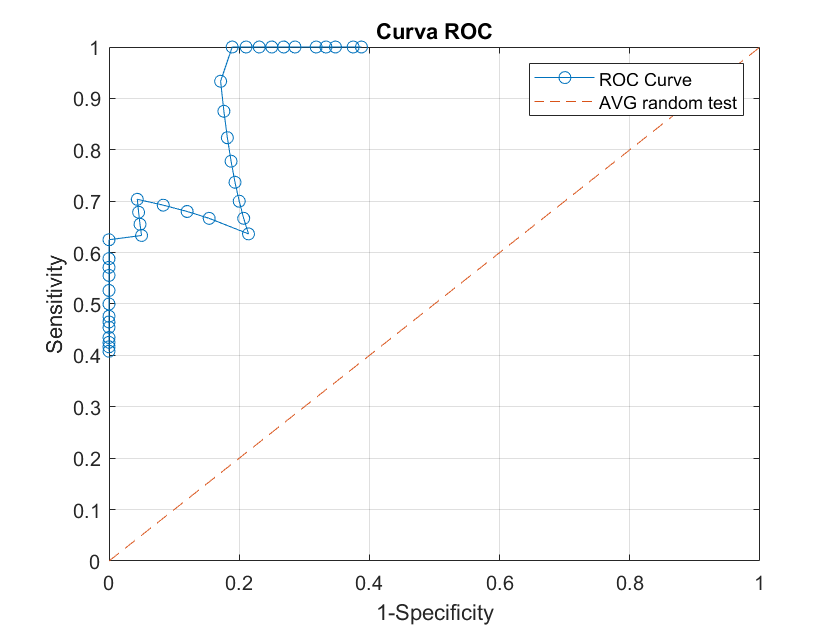

figure;
plot((1-specificity), sensitivity,'o-'); grid on;
xlabel('1-Specificity');
ylabel('Sensitivity');
grid on; hold on; plot([0 1],[0 1], '--');
legend('ROC Curve','AVG random test');
title('Curva ROC');

#### **CURVE KAPLAM-MEIER e ANALISI DI SOPRAVVIVENZA**

*Load the survival.mat file containing survival data and gene expression data from 221 hepatocellular carcinoma (HCC) samples.*

*• Compute the following prognostic index to identify low risk and high risk patients:*


$$PI= 0.384\cdot RTN3 - 0.561\cdot SOCS2 - 0.43\cdot UPB1$$


*• Draw the Kaplan-Meier curve of the high risk group*

*• Compare survival curves of the two groups of patients and apply the Logrank test [matlab function: logrank.m]*

*• Is the prognostic index effective in separating two groups of statistically different survival outcome?*

Le **curve di Kaplam-Meier **mettono in relazione la dipendenza tra il tempo dopo la diagnosi di una patologia e la probabilità sopravvivenza di un paziente. E' una curva a gradini dove ogni gradino identifica un evento, ed il valore della curva in quel punto è la probabilità che un paziente sopravviva dopo la diagnosi fino all'istante di tempo dell'evento. E' possibile che di alcuni soggetti non sia disponibile la data di morte: questi pazienti si trattano come esclusioni, di cui si utilizzano i dati fino a quando sono disponibili

La probabilità di sopravvivenza viene calcolata con la produttoria

 
$$S(t) = \prod_{t_i < t} \frac{r(t_i)-d(t_i)}{r(t_i)}   =   \prod_{t_i < t}1- \frac{d(t_i)}{r(t_i)}$$


dove:

- ***r*** = Numero di soggetti a rischio

- ***d*** = Numero di eventi

Diverse curve riferite a diverse popolazioni possono essere confrontate con un **logrank-test. **

I dati a disposizione sono:

- `data: `contiene i dati di espressione genica (21247geni x 221 soggetti)

- `genes: `contiene i nomi dei 21247 geni

- `samples: `contiene i nomi dei 221 soggetti

- `times: `contiene l'istante di tempo degli eventi per ogni soggetto (221 tempi riferiti all'evento di morte/esclusione per i 221 soggetti)

- `censored_flags: `contiene i flags che indicano se l'evento *i-esimo *è un evento di morte (0) o di esclusione (1)

load("survival.mat");

Ricaviamo l'espressione relativa dei geni di interesse (*RTN3, SOCS2, UPB1*): viene impostata pari a 2 se l'espressione è sopra il valore mediano nel gene, altrimenti è impostata a 1. Le variabili `RTN3, SOCS2, UPB1 `contengono 1 o 2 se il soggetto ha il suddetto gene sottoespresso o sovraespresso. 

% Espressione relativa [1=low, 2=high] di RTN3
RTN3 = data(genes=='RTN3',:);
high_RTN3 = RTN3>median(RTN3);
low_RTN3 = RTN3<=median(RTN3);
RTN3(high_RTN3) = 2;
RTN3(low_RTN3) = 1;

% Espressione relativa [1=low, 2=high] di SOCS2
SOCS2 = data(genes=='SOCS2',:);
high_SOCS2 = SOCS2>median(SOCS2);
low_SOCS2 = SOCS2<=median(SOCS2);
SOCS2(high_SOCS2) = 2;
SOCS2(low_SOCS2) = 1;

% Espressione relativa [1=low, 2=high] di UPB1
UPB1 = data(genes=='UPB1',:);
high_UPB1 = UPB1>median(UPB1);
low_UPB1 = UPB1<=median(UPB1);
UPB1(high_UPB1) = 2;
UPB1(low_UPB1) = 1;

Si calcola poi l'indice prognostico richiesto, uno per ogni soggetto nel dataset.

PI = 0.384*RTN3 - 0.561*SOCS2 - 0.43*UPB1;

Da qui poi si classificano i soggetti come ad alto rischio o a basso rischio, sempre confrontando l'indice prognostico di ognuno di essi con il valore mediano

highrisk = PI>median(PI);
lowrisk = PI<=median(PI);

Estraiamo poi gli eventi in `times `e in `censored_flag `riferiti ai pazienti ad alto rischio e a basso rischio.

time_highrisk = times(highrisk);
flag_highrisk = censored_flags(highrisk);
time_lowrisk = times(lowrisk);
flag_lowrisk = censored_flags(lowrisk);

Costruiamo ora la curva Kaplam-Meier **solo per i soggetti ad alto rischio. **Estraiamo innanzitutto i tempi di evento (di morte) `event `e di esclusione `censored `per i soggetti ad alto rischio

N = length(time_highrisk); % Numero di soggetti ad alto rischio
event = time_highrisk(flag_highrisk==0)'; % Tempi di EVENTO per soggetti ad alto rischio
censored = time_highrisk(flag_highrisk==1)'; % Tempi di ESCLUSIONE per soggetti ad alto rischio

Definiamo l'asse dei tempi `t1 `con la funzione `unique` che mantiene solo i duplicati del vettore `event `e riordinandoli in ordine crescente; inizializziamo anche il vettore con gli eventi e le esclusioni riferiti ad ogni istante di tempo. 

t1 = [0 unique(event)];
event1 = [];
c1 = [];

Ricaviamo poi, per ogni posizione di `event1, `la quantità di eventi riferiti all'istante di tempo nel vettore `t1 `nella stessa posizione del vettore.

for i=1:length(t1)
    event1 = cat(2, event1, nnz(event == t1(i)));
end

Effettuiamo il conteggio anche per le esclusioni, che si contano in questo caso tra eventi successivi piuttosto che in corrispondenza di un evento.

for i=1:length(t1)-1
    c1 = cat(2,c1,nnz(t1(i)<censored & censored<t1(i+1)));
end
c1 = cat(2,c1,nnz(censored>=t1(end))); % Escluisioni oltre l'ultimo evento 

Il numero di soggetti a rischio per ogni istante di tempo `nt `ha la stessa lunghezza del vettore degli eventi: viene inizializzato tutto con il valore del numero di soggetti a rischio, da cui poi vengono sottratti i soggetti che vanno incontro ad un evento o che vengono esclusi.

nt = N*ones(1, length(t1));
for j = 2:length(t1)
    nt(j) = nt(j-1) - event1(j-1) - c1(j-1);
end

Calcoliamo la **probabilità di sopravvivenza come l'opposto della probabilità di evento**. La probabilit di evento `f` ad ogni istante di tempo è pari al rapporto tra numero di eventi e il numero di soggetti a rischio. Per plottare la Kaplam-Meier si calcola la produttoria con `cumprod`

f = event1./nt;
s = 1-f;
KM = cumprod(s);

Plottiamo la Kaplan-Meier con una curva a gradini:

figure; 
stairs(t1, KM); grid on; title('Curva di Kaplan-Meier - Soggetti ad alto rischio')
xlabel('Tempo di Evento'); ylabel('Probabilità di sopravvivenza');

Effettuiamo il test statistico con la funzione `logrank, `che riceve in ingresso i tempi e i flags per le due popolazioni.

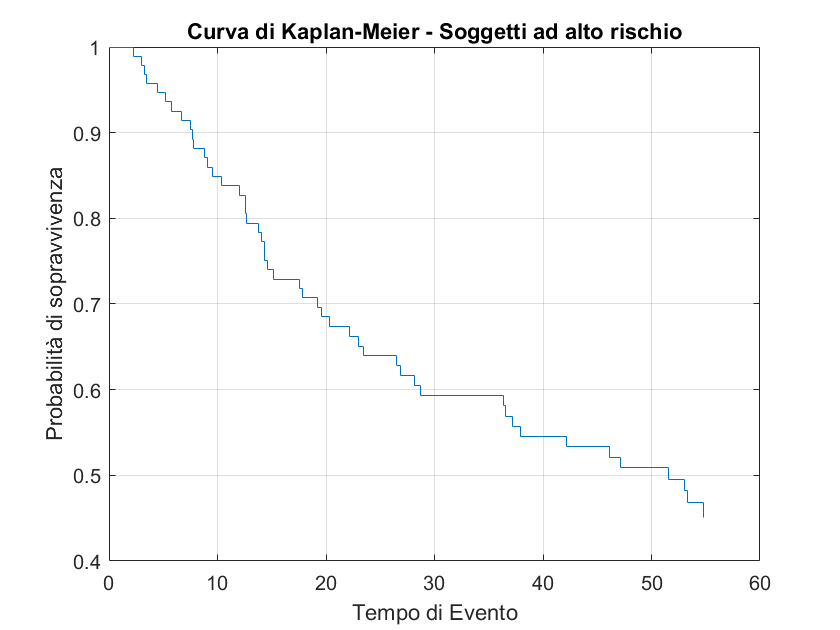

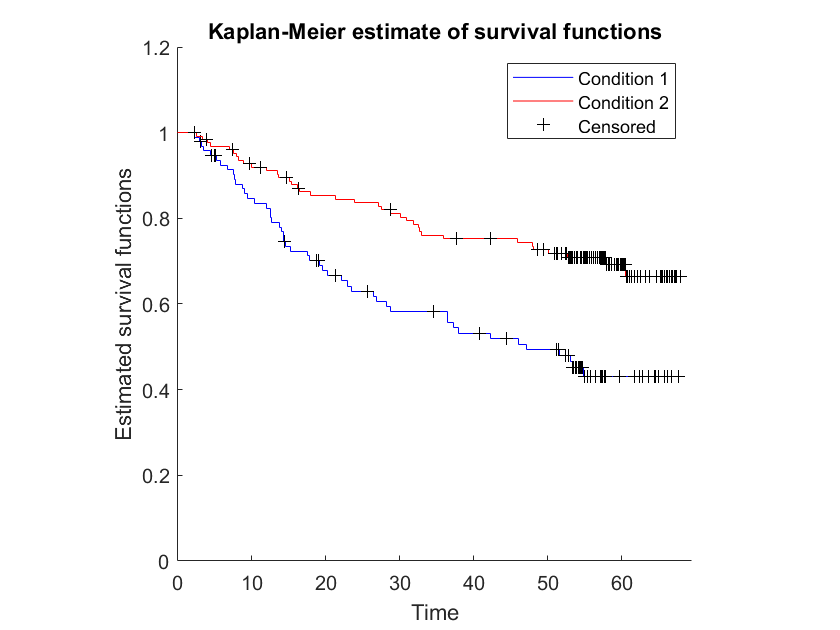

p = 2.2549e-04

		The survival functions are statistically different


logrank([time_highrisk,flag_highrisk],[time_lowrisk,flag_lowrisk])